# Mohammadreza Arani

## Convex Optimization

## 810100511

## Hw8 - Q3:

clear;
clc;
close all;
% Load Data:
run('simple_portfolio_data.m');

% Out problem is a QP with an affine constraint:
%% unconstrained:
cvx_begin

    variable x_unconstrained(n)
        minimize(quad_form(x_unconstrained,S))
    % Constraints:
        subject to
        sum(x_unconstrained)    ==     1          ;
        pbar'*x_unconstrained   ==  x_unif' * pbar;
cvx_end

 
Calling SDPT3 4.0: 21 variables, 19 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 19
 dim. of socp   var  = 21,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.5e+00|2.6e+00|2.4e+01| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.5e-06|4.7e-02|2.1e+00| 1.324089e+00 -6.530277e-01| 0:0:00| chol  1  1 
 2|0.996|0.989|2.6e-08|5.2e-03|2.2e-02|-9.923533e-02 -1.197667e-01| 0:0:00| chol  1  1 
 3|0.989|0.988|5.9e-09|5.3e-04|2.4e-04|-1.148472e-01 -1.149626e

## long-only:

cvx_begin
    variable x_long(n)
    % Objective:
    minimize(quad_form(x_long,S))
    
    subject to % Constraints:
        x_long         >= 0;
        sum(x_long)    ==      1       ; 
        pbar'*x_long   ==  x_unif'*pbar;
cvx_end

 
Calling SDPT3 4.0: 43 variables, 21 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 21
 dim. of socp   var  = 21,   num. of socp blk  =  1
 dim. of linear var  = 20
 dim. of free   var  =  2 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.7e+01|1.7e+01|2.1e+03|-1.563897e-10  0.000000e+00| 0:0:00| chol  1  1 
 1|0.990|0.767|3.8e-01|4.0e+00|6.0e+02| 1.528328e+01 -8.971290e-01| 0:0:00| chol  1  1 
 2|1.000|0.990|1.4e-06|4.8e-02|1.9e+01| 1.192556e+01 -1.426141e-01| 0:0:00

## Constrained short Portfolio:

cvx_begin

variable x_shortconstr(n)
% Objective:
minimize(quad_form(x_shortconstr,S))

subject to % Constraints:
    sum(pos(-x_shortconstr))   <=    0.5        ;
    sum(x_shortconstr)         ==    1          ;
    pbar'*x_shortconstr        ==   x_unif'*pbar;
cvx_end

 
Calling SDPT3 4.0: 64 variables, 41 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 41
 dim. of socp   var  = 21,   num. of socp blk  =  1
 dim. of linear var  = 41
 dim. of free   var  =  2 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.7e+01|2.4e+01|4.4e+03| 5.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.719|1.1e+00|6.9e+00|1.5e+03| 2.786607e+01 -1.085812e+00| 0:0:00| chol  1  1 
 2|1.000|0.986|2.5e-06|1.1e-01|4.7e+01| 2.433295e+01 -1.674058e-01| 0:0:00

disp("unconstrained sd:  " + num2str(sqrt(quad_form(x_unconstrained,S))  ))

unconstrained sd:  0.018607


disp("long only sd:  " + num2str(sqrt(quad_form(x_long,S)))  )

long only sd:  0.050658


disp("constrained short sd:  " + num2str(sqrt(quad_form(x_shortconstr,S)))  )

constrained short sd:  0.020995




disp("x_unif sd:  " + num2str(sqrt(quad_form(x_unif,S)))  )

x_unif sd:  0.087036


novals=100;
r_long = [];
r_shortconstr = [];
sd_long = [];
sd_shortconstr = [];
muvals = logspace(-1,4,novals);
for i=1:novals
mu = muvals(i);
%long only
    cvx_begin
    cvx_quiet(true)
        variable x(n)
        maximize(pbar'*x - mu*quad_form(x,S))
        subject to
        x        >=   0;
        sum(x)   ==   1;
    cvx_end
    r_long = [r_long, pbar'*x];
    sd_long = [sd_long, sqrt(x'*S*x) ];
%constrained short
    cvx_begin
    cvx_quiet(true)
        variables x(n)
        maximize(pbar'*x - mu*quad_form(x,S))
        subject to
        sum(x)       ==   1 ;
        sum(pos(-x)) <=  0.5;
    cvx_end
    r_shortconstr = [r_shortconstr, pbar'*x];
    sd_shortconstr = [sd_shortconstr, sqrt(x'*S*x)];
end


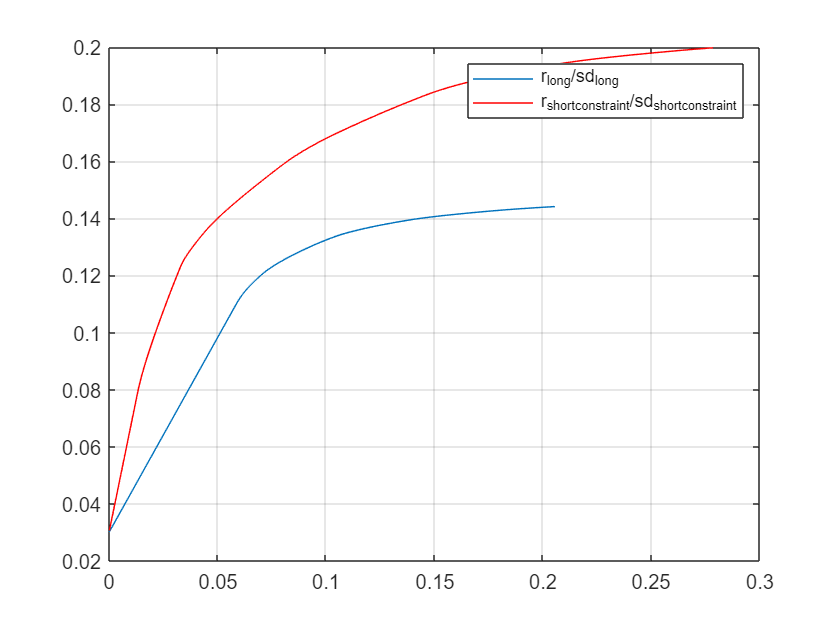

Fig7=figure();
plot(sd_long, r_long);
hold on;
plot(sd_shortconstr, r_shortconstr, 'r');
grid on
legend('r_{long}/sd_{long}','r_{shortconstraint}/sd_{shortconstraint}')